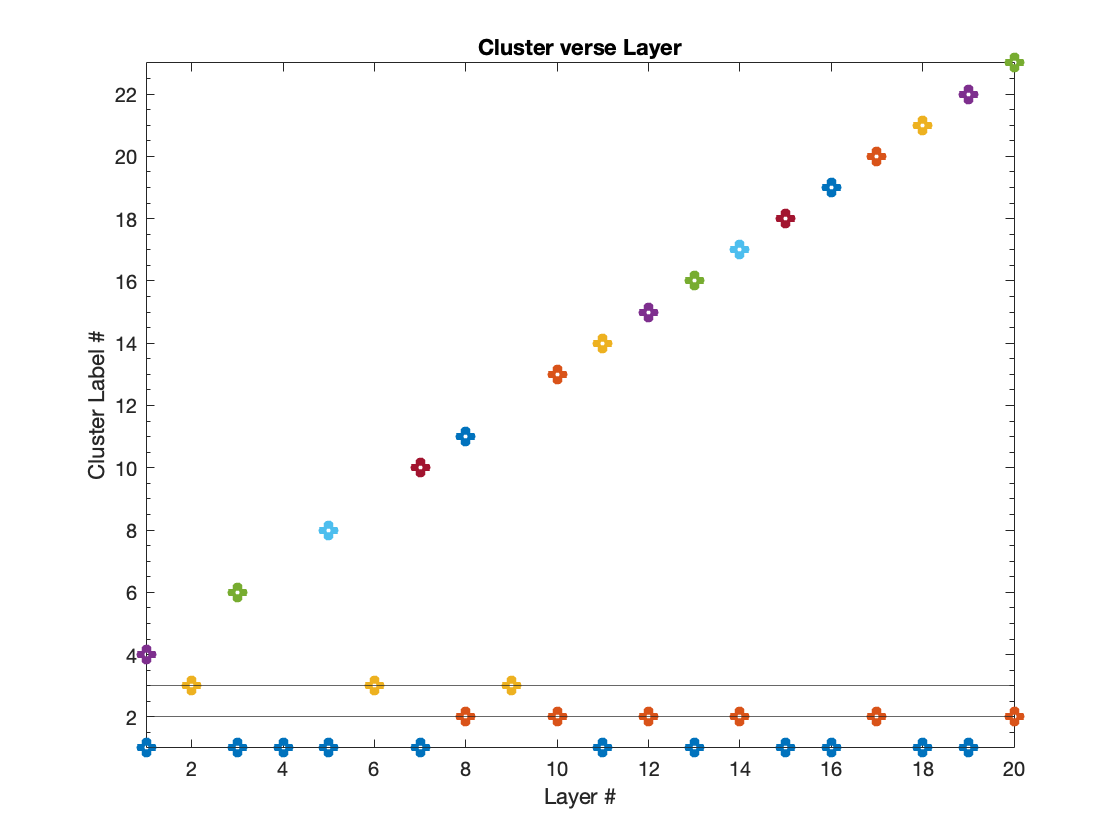

%Finding out what clusters belong to which layers


load("findK_eg95_d5_A_threshold09.mat", "kc","k","kp", "Z");

Al = importdata("A_threshold_p09.mat");

load("notFixed_eg95_d5_k3_thresholdA09.mat", "ClustersSupra");


kpl=kp;
ClustersSupra = ClustersSupra; %length(unique(ClustersSupra))
k=k;

un_len = max(ClustersSupra);

colors = random_color(un_len); %fix so its not all same colors

L = 20; %20 layers
x=1;
z=64;
y=1;

clusterssupra_total = [];

cluster_layer_strength= [];

cluster_layer = zeros(un_len,L);

layer_nodes_per_cluster = []; %matrix that is un_len each matrix has zeros(k_labels,64);

for i=1:un_len
    layer_nodes_per_cluster = [layer_nodes_per_cluster, {zeros(L,64)}];
end


cluster_strength_layer = cell(L,1,kc); %cretaes the intercluster strength per layer per cluster
layers_in_cluster = cell(1,kc); %tells you which layers are in the cluster
sum_of_edges = cell(L,1,kc); %

for i=1:kc
    for subject=1:L
        cluster_strength_layer{subject,1,i}= zeros(64,64);
    end
end






for cindex=1:L
    
    A = Al{cindex};

   
    k_labels = unique(ClustersSupra(x:z));
    clusterssupra_total = [clusterssupra_total, {k_labels}];
    
    
    for index=1:length(k_labels)
        label = k_labels(index);
        cluster_layer(label,cindex) = 1; %mark present in layer
        new_nodes = find(ClustersSupra(x:z)==label)'; 
        

        
        if label <= kc
            past=new_nodes(1); 
            layers_in_cluster{label} = [layers_in_cluster{label} cindex];
            
            for new=1:length(new_nodes)
                if new_nodes(new) >= past
                    for future=1:length(new_nodes)
                        future_node = new_nodes(future);
                        cluster_strength_layer{cindex,1,label}(past,future_node) = A(past,future_node);
                        %check = cluster_layer_strength{cindex,1,i}(past,future_node);
                        %check_old = A(past,future_node);
                    end
                    past = new_nodes(new);
                end
            end
            
          % cluster_layer_strength{cindex,1,label}(x_node,y_node) = 
        end
        
            
        for new=1:length(new_nodes)
            layer_nodes_per_cluster{1,label}(cindex,new_nodes(new)) = 1;
        end
        
    end

    x=x+64;
    z=(x+63);
  
end


%INTERCLUSTER STRENGTH SUM
for i=1:kc
    for subject=1:L
        B = cluster_strength_layer{subject,1,i};
        sum_of_edges{subject,1,i}= sum(B,'all');
    end
end



%Plotting data stored

figure;

M = cluster_layer;
% Loop over rows
for i = 1:size(M, 1)
    % Find column indices where there is a 1
    ind = find(M(i,:)==1);
    
    % Plot indices against row number
    plot(ind, repmat(i, size(ind)), 'o','LineWidth',4);
    hold on;
end

% Set axis labels and limits
xlabel('Layer #');
ylabel('Cluster Label #');
xlim([1 size(M, 2)]);
ylim([1 size(M, 1)]);
title("Cluster verse Layer");
set(gca,'YMinorTick', 'on');
yline(1:3);
hold off;

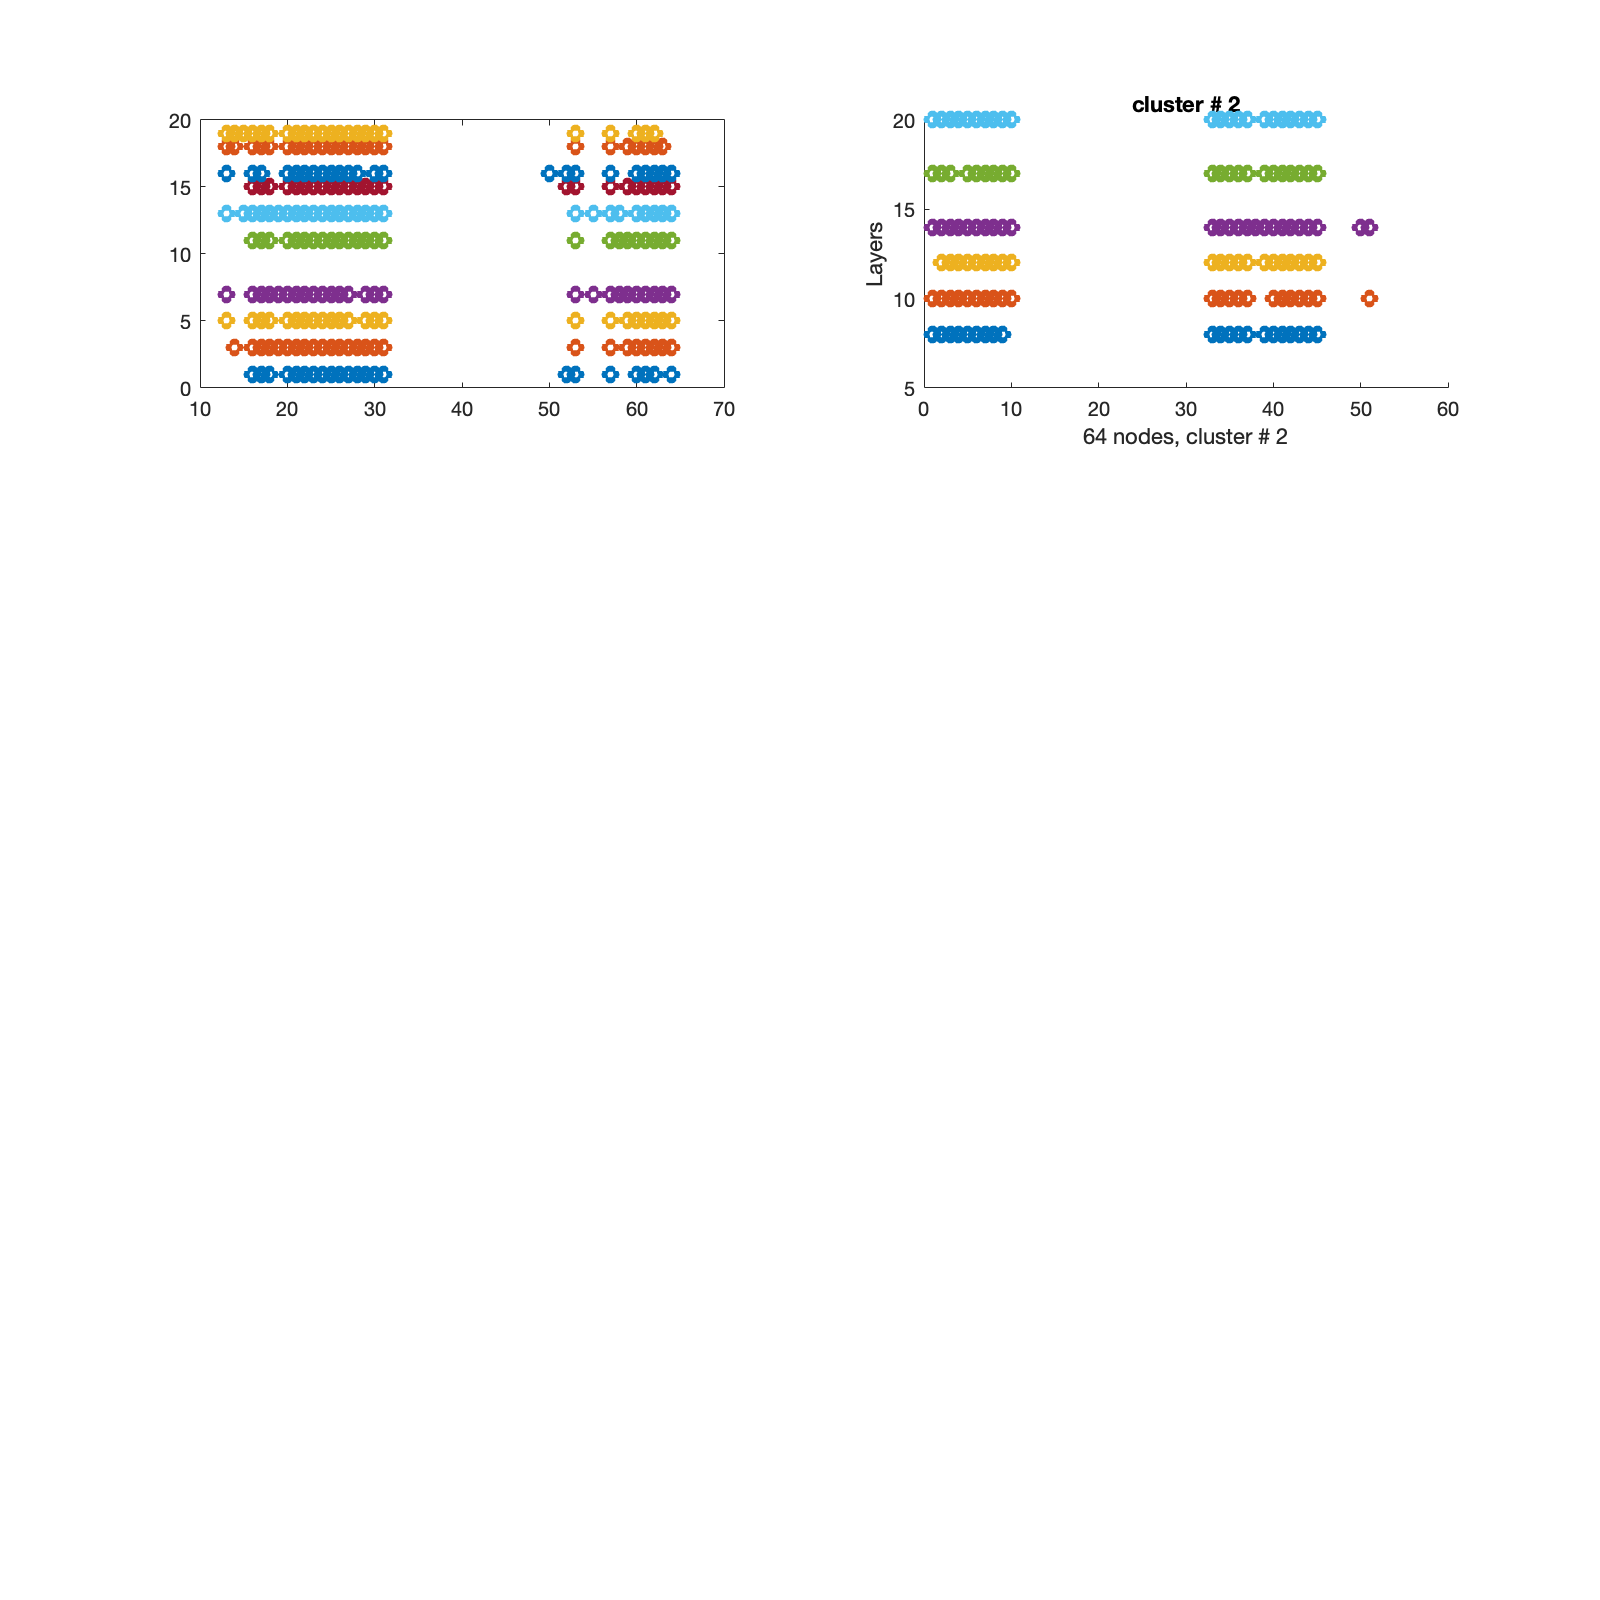




figure;
figure('Position', [0 0 800 800])

P= layer_nodes_per_cluster;


subplot_rows = length(P);
subplot_cols = 1;

% Loop over rows

%This graph helps identify the outliters for layers and nodes per kc
%cluster
tiledlayout(4,2)

prob_of_node_per_cluster = []; % Probability of Nodes
 
for i = 1:length(P)
    prob_of_node_per_cluster = [prob_of_node_per_cluster, {zeros(64,1)}];
    M = P{i};
    
    
     if i > 2
         break
     end
    nexttile
     %subplot(8,1, i) % 'Position',  [0.1 0.1 0.8 0.8]) %, 'Position', [x y w h])
    % Set axis labels and limits
    title(sprintf('cluster # %d',i))
    xlabel(sprintf('64 nodes, cluster # %d',i));
    ylabel('Layers');
    for n = 1:size(M, 1)

       % Find column indices where there is a 1
       ind = find(M(n,:)==1);
            
    
       for in = 1:length(ind)
          prob_of_node_per_cluster{1,i}(ind(in),1) = prob_of_node_per_cluster{1,i}(ind(in),1)+1;
       end
       
       if n~=4 %remove outlier L=4
            % Plot indices against row number
            plot(ind, repmat(n, size(ind)), 'o','LineWidth',3);
            
            hold on;
        end

        
        % Plot indices against row number
        %plot(ind, repmat(n, size(ind)), 'o');
        %hold on;
    end
    hold off;
    
    %pos = get(gcf, 'Position');
    %set(gcf, 'Position',pos+[0 -500 0 500])


end

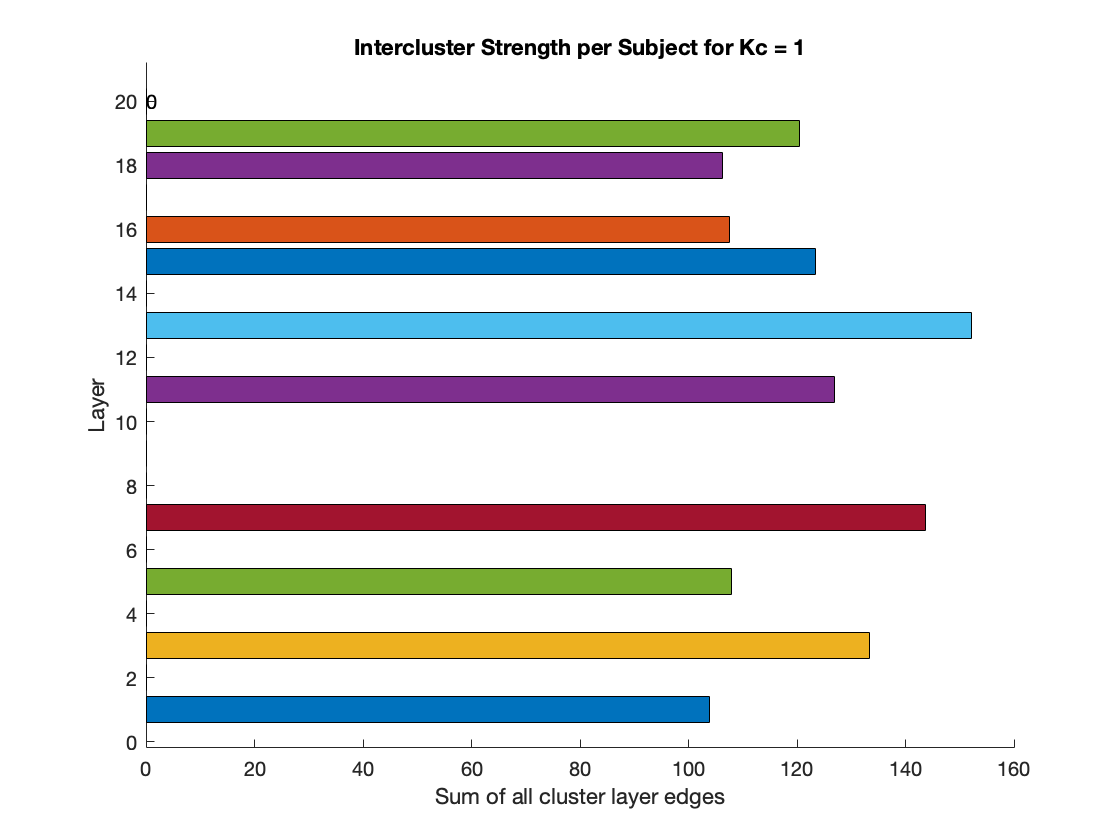

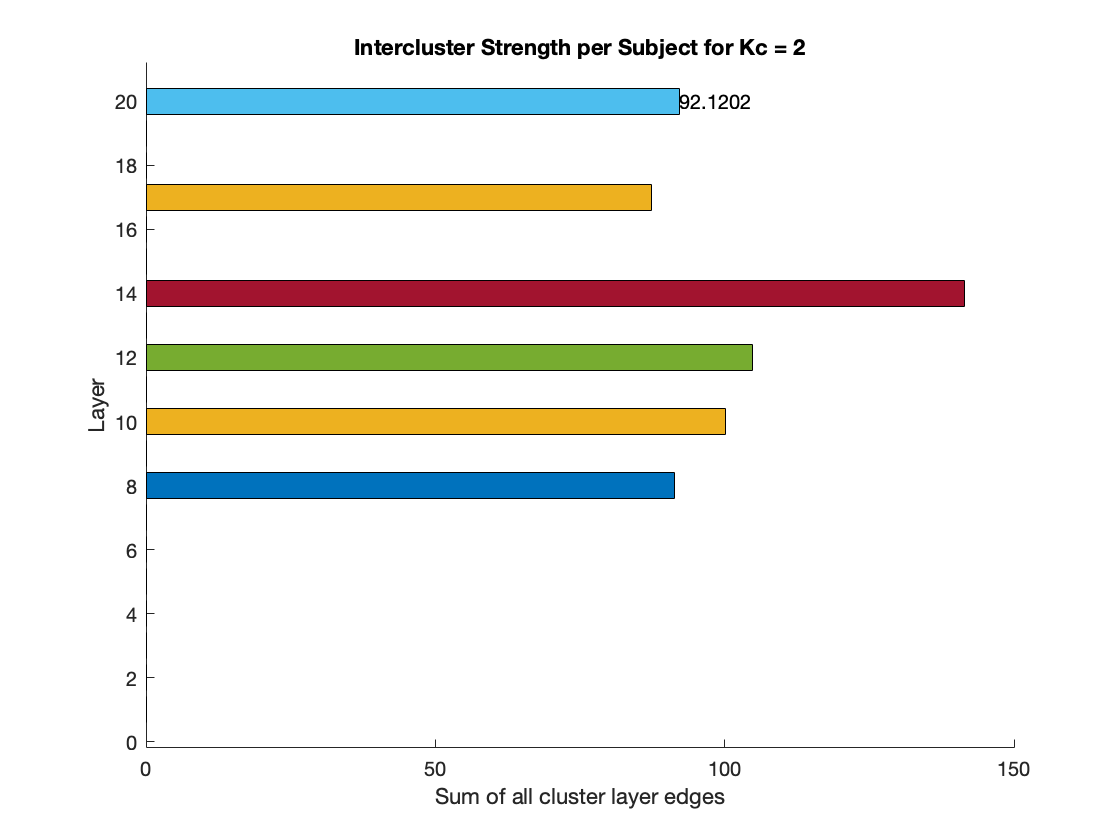



for cindex = 1:kc
    
    if cindex == 3 %outlier removing kc==3
        break
    end
    
    % Create a vector of row indices for the y-axis
    sumy = sum_of_edges(:,:,cindex);
    
  
    %removing outlier L=4
    sumy{4,1} = 0;
    
    % Create a vector of row indices for the y-axis
    y = 1:size(sumy, 1);
    
    % Create a figure for the bar graph
    figure;
    
    % Loop over the rows of the sumy variable and plot the values as a bar graph
    for i = 1:size(sumy, 1)
        % Extract the values from the current row of the sumy variable
        row_values = cell2mat(sumy(i,:));
        hold on
        % Plot the values as a horizontal bar graph
        barh(y(i), row_values);
        
    
    end
    
        hold off
        % Add labels to the bars
        text(row_values, y(i)*ones(size(row_values)), num2str(row_values), 'HorizontalAlignment', 'left', 'VerticalAlignment', 'middle');
        
        % Add a title to the plot
        title(sprintf('Intercluster Strength per Subject for Kc = %d', cindex));
        
        % Set the y-axis label
        ylabel('Layer');
        xlabel("Sum of all cluster layer edges")
end